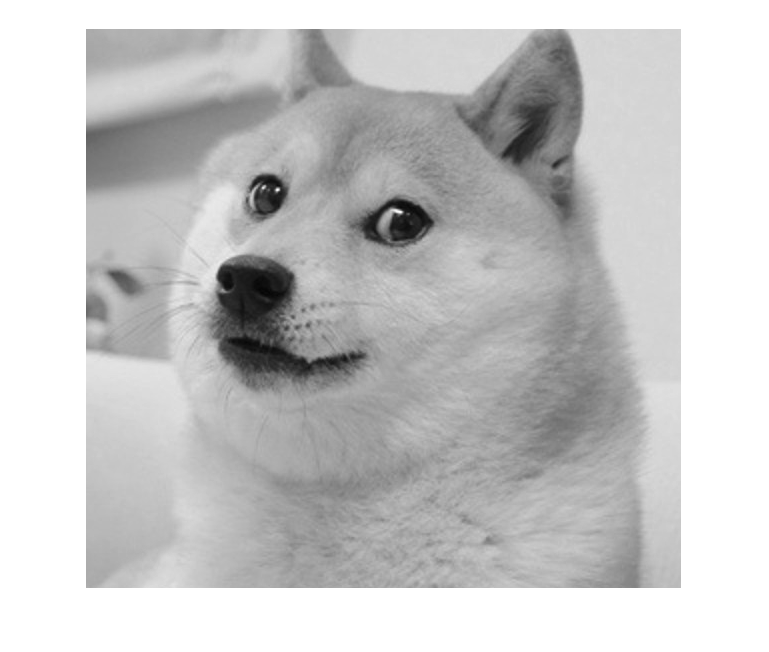

img = imread('dog.bmp');
img = rgb2gray(img);
figure(1)
imshow(img)

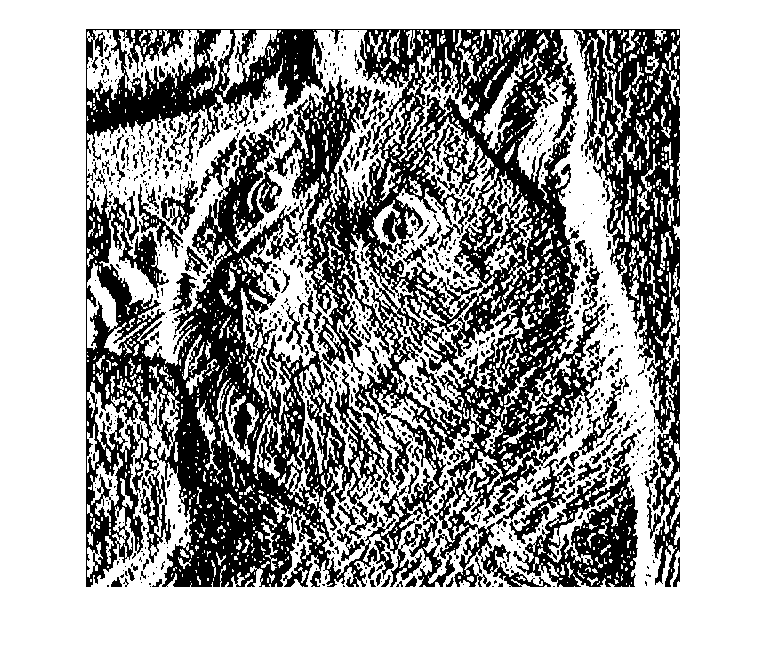

[row,col] = size(img);
img = double(img);
w1 = [-1 -2 -1; 0 0 0 ; 1 2 1];
w2 = [-1 0 1; -2 0 2 ; -1 0 1];

% a %vert_edge
% b %horz_edge
for x = 2:1:row-1;
    for y =2:1:col-1;
        vert_edge(x,y) = ...
            w1(1)*img(x-1,y-1)+...
            w1(2)*img(x-1,y)+...
            w1(3)*img(x-1,y+1)+...
            w1(4)*img(x,y-1)+...
            w1(5)*img(x,y)+...
            w1(6)*img(x,y+1)+...
            w1(7)*img(x+1,y-1)+...
            w1(8)*img(x+1,y)+...
            w1(9)*img(x+1,y+1);
        
        horz_edge(x,y) = ...
            w2(1)*img(x-1,y-1)+...
            w2(2)*img(x-1,y)+...
            w2(3)*img(x-1,y+1)+...
            w2(4)*img(x,y-1)+...
            w2(5)*img(x,y)+...
            w2(6)*img(x,y+1)+...
            w2(7)*img(x+1,y-1)+...
            w2(8)*img(x+1,y)+...
            w2(9)*img(x+1,y+1);
    end
end

figure(2)
% vert_edge = vert_edge(: , 1:col/3);
imshow(vert_edge)

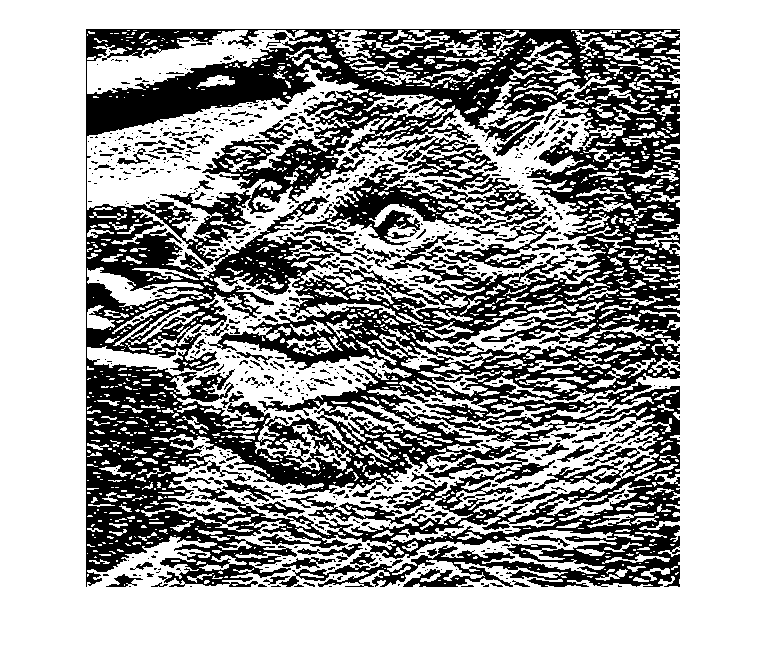


figure(3)
% horz_edge = horz_edge(: , 1:col/3);
imshow(horz_edge)